clc;
clearvars;

Variables:

P3Q2_LPC = 3;
P3Q2_HPC = 5;
y_c = 1.4;
y_t = 1.33;
M = 0.2;
ETHA_Comp = 0.8;
ETHA_Comb = 0.95;
T3 = 1600;
Cp_hot = 1150;
Cp_cold = 1000;
LCV = 43 * 10^6;
ETHA_turb = 0.85;
R = 287.5;

Height input, temperature and pressure output:

h = 10000;

Pb = 101.325;
Tb = 288.2;
hb = 0;
Lb = 0.0065;
g = 9.80665;
Mol = 0.0289644;
R1 = 8.3144598;
P0 = Pb * ((Tb - (h - hb) * Lb)/Tb).^((g * Mol)/(R1 * Lb))

P0 = 26.4439


T0 =(h * Lb) + Tb

T0 = 353.2000

Intake conditions:

W0 = 150

W0 = 150

Station 1: LPC (low pressure compressor) inlet

T1 = T0 * (1 + ((y_c-1)/2) * M^2)

T1 = 356.0256

P1 = P0 * (T1/T0)^(y_c/(y_c-1))

P1 = 27.1918

W1 = W0                             % Nothing is added to the flow

W1 = 150

Station 1_5: LPC

P1_5 = P1 * P3Q2_LPC

P1_5 = 81.5753

T1_5 = T1 * (1 + ((P1_5/P1)^((y_c - 1)/y_c)- 1)/ETHA_Comp)

T1_5 = 520.1259

W1_5 = W0                           % Nothing is added to the flow

W1_5 = 150

Station 2: HPC (high pressure compressor)

P2 = P1_5 * P3Q2_HPC

P2 = 407.8763

T2 = T1_5 * (1 + ((P2/P1_5)^((y_c - 1)/y_c)- 1)/ETHA_Comp)

T2 = 899.7005

W2 = W1_5                           % Nothing is added to the flow

W2 = 150

Station 3: Combustor

P3 = P2 * ETHA_Comb

P3 = 387.4824

T3

T3 = 1600

Q = W2 * Cp_hot * (T3 - T2);
WF = Q/LCV;
W3 = WF + W2

W3 = 152.8093

Station 3_5: HPT (high pressure turbine)

WHPC = W2 * Cp_cold * (T2 - T1_5);
T3_5 = T3 - (WHPC/(W3 * Cp_hot))

T3_5 = 1.2760e+03

P3_5 = P3 * (1- (1-(T3_5/T3))/ETHA_turb)^(y_t/(y_t- 1))

P3_5 = 129.4076

W3_5 = W3                           % Nothing is added to the flow

W3_5 = 152.8093

Station 4: LPT (low pressure turbine)

WLPC = W1 * Cp_cold * (T1_5 - T0);
T4 = T3_5 - (WLPC/(W3 * Cp_hot))

T4 = 1.1335e+03

P4 = P3_5 * (1 - (1-(T4/T3_5))/ ETHA_turb)^(y_t/(y_t- 1))

P4 = 73.3576

W4 = W3_5                           % Nothing is added to the flow

W4 = 152.8093

Station 5: Nozzle 

T5 = T4

T5 = 1.1335e+03

P5 = P4

P5 = 73.3576

W5 = W4

W5 = 152.8093

Calculating static conditions:

Ps = P5/(1 + (y_c - 1)/2)^(y_c/(y_c-1))

Ps = 38.7535

Ts = T5/(1 + (y_c - 1)/2)

Ts = 944.5991

Calculating Jet Velocity:

Vj = sqrt(y_c * R * Ts)

Vj = 616.6045

Calculate static density:

rho = Ps * 1000/(R * Ts)

rho = 0.1427

Calculate nozzle area required:

An = W0./(Vj * rho)

An = 1.7047

Calculate Thrust: (N)

Fn = (W0 + WF).* Vj + An.* (Ps - P0).* 1000

Fn = 1.1521e+05

Calculate SFC (specific fuel consumption): (g/s kN)

SFC = (WF/Fn) * 1000000

SFC = 24.3850

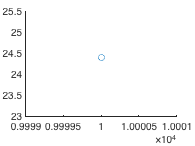

s =   Scatter with properties:

              XData: 10000
              YData: 24.3850
              ZData: [1×0 double]
           SizeData: 36
              CData: [0 0.4470 0.7410]
             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000

  Show all properties


s = scatter (h, SFC)